# eventospie_carrera

Detección de eventos en la carrera

## Syntax

`[IC,FC]=eventospie_carrera(gyr,th,freq)`

`[IC,FC,MaxS,MinS,MVP,MP]=eventospie_carrera(gyr,th,freq,gyrx)` 

## Description

`[``IC,FC``]=eventospie_carrera(``gyr,th,freq``)`  tomando como entrada la velocidad angular en el eje mediolateral `gyr`, muestreada a cierta frecuencia `freq`, y tras realizar un proceso interno de filtrado (apoyado en filtro0 de la SP-TB) con una frecuencia de corte `th`, se identifican los eventos de contacto inicial IC y final FC del pie en el que esta el sensor. 

`[``IC,FC,MaxS,MinS,MVP,MP``]=eventospie_carrera(``gyr,th,freq, gyrx``) `es la versión completa, que añade otras 4 detecciones, y requiere como entrada el giróscopio en la dirección antero-posterior `gyrx`. 

Los eventos se describen en: Athletic and sport issues in musculoskeletal rehabilitation, David J_ Magee; James E_ Zachazewski; William S_ Quillen; Ed. Elsevier Inc, Health, 2011. 

La siguiente es una gráfica adaptada del libro (Fig. 18-1) con anotaciones: 

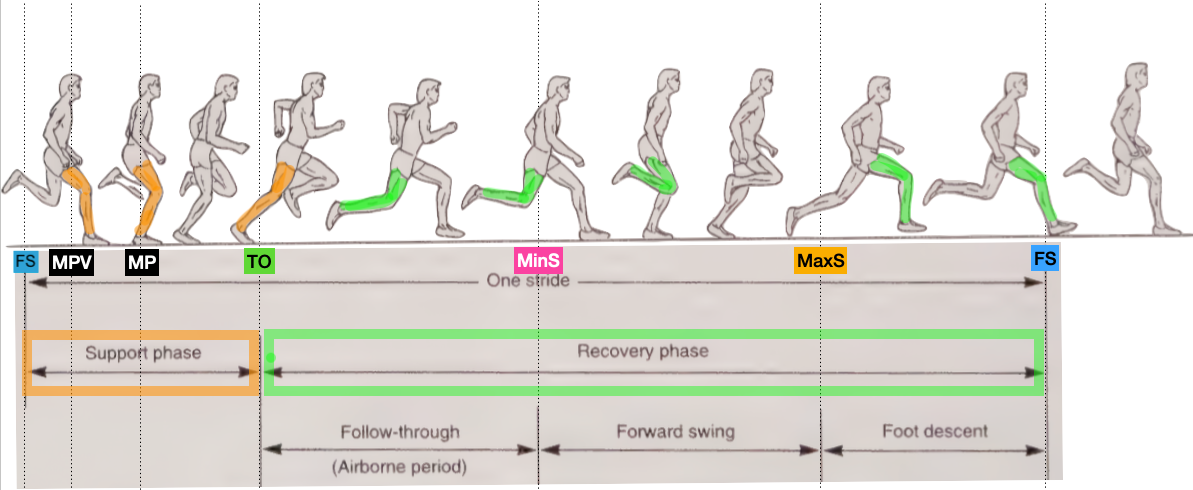

La fase de soporte suele tener duraciones del 30-40% del ciclo.

- FS (FootStrike): The moment the foot first contacts the ground, initiating the stance phase.

- MPV (Maximum Pronation Velocity): The point at which the foot undergoes the fastest rate of pronation (inward roll of the foot).

- MP (Maximum Pronation): The point where the foot reaches its maximum inward roll during the stance phase.  

- TO (ToeOff): The moment the foot leaves the ground, ending the stance phase and starting the swing phase.

- Min Swing (Maximum Backward Swing): the point in the gait cycle where the swinging leg reaches its furthest backward position.

- Max Swing (Maximum Forward Swing): the point in the gait cycle where the swinging leg reaches its furthest forward position.

## Examples

Suponemos que tenemos una señal de giro ML disponible obtenida con un sensor a 120Hz:

% filtro y deteccion (requiere la TB de SP de Matlab): 
freq=120;
th=150;
[IC,FC]=eventospie_carrera(gyroml,th,freq);

## Argumentos de entrada

%    gyr           - vector con la velocidad de giro en el eje mediolateral
%    th            - velocidad mínima a alcanzar para detectar eventos. Aconsejado 150
%    frecuencia    - frecuencia de muestreo.
%    gyrx           - vector con la velocidad de giro en el eje antero-posterior

## Argumentos de salida

%    IC : muestra en las que se ha detectado el contacto inicial con el suelo
%    FC : muestra en las que se ha detectado el final del contacto con el suelo
%    Max Swing (MaxS)   
%    Min Swing (MinS)
%    Pronation Velocity (MPV)
%    Max. Pronation (MP)